# Running Simulations Only


close all 
clear all

runsim = 1;
old = 1; % if 1, uses old parameters. If 0, uses young.

% will load previous simulation results to save time
if ~runsim
    load simresults/simresults_04272021.mat
end


## Set Old/Young Metabolic Parameters

global param

%metabolic data parameters: etotal = esit + emove = ao*to + a*t + (b*d^i)/T

if old == 1 % old - used if "old" = 1
    param.myc0 = -9; % accuracy parameters; shifts logistic to the right with scaling
    param.myc1 = 15; % accuracy parameters; shifts logistic to the left with scaling
    param.mya = 77; % effort offset 
    param.myb = 20; %b in metabolic equation (new = 15)
    param.myao = 69; % resting rate for older adults
%     param.myao = 77; % resting rate for older adults
    param.myi=0.88;  %exponent on distance
    
elseif old == 0 % young - used if "old" = 0        
    param.myc0 = -5; % accuracy parameters; shifts logistic to the right with scaling
    param.myc1 = 10; % accuracy parameters; shifts logistic to the left with scaling
    param.mya = 77; % effort offset 
    param.myb = 12; %b in metabolic equation (new = 11)
    param.myao = 77; % resting rate for older adults
    param.myi=1.23;  %exponent on distance
end

%both
% param.myc0to = -1; % Used in optimization
% param.myc1to = 10; % Used in optimization
param.myc0to = -6; % -8.75; % Used in new RT function
param.myc1to = 20; % 35; % Used in new RT function
param.myeffscale = 1; 

%distance
d=0.1;

%range of alpha values
myalphas=20:100;
% myalphas=40:110; % iterating over different levels of reward to see what happens

%range of SCALING on effort, alpha, and probability terms - used in
%optimization
myeffscales = 0.8:0.1:1.2;
myalphascales= 0.8:0.1:1.2;
myprobscales = 0.8:0.1:1.2;


## Run Simulation


% use this index to focus on alpha of a certain value
alphaind=find(myalphas==70);
alphascaleind=find(myalphascales==1);
effscaleind=find(myeffscales==1);
probscaleind= find(myprobscales==1);
myrange=find(myalphascales>=0.7);

tic
if runsim
    for i=1:length(myalphas) %loop over all alpha values
        param.myalpha=myalphas(i);
        %disp(i)
        for j=1:length(myeffscales) %loop over effort scaling
            param.myeffscale=myeffscales(j);
            for k=1:length(myalphascales) %loop over alpha scaling
              param.myalphascale=myalphascales(k);  
              for m=1:length(myprobscales) %loop over probability scaling
                  param.myprobscale=myprobscales(m);
                    
                  mycond= (j==effscaleind) + (k==alphascaleind) + (m==probscaleind);
                  
                  if (mycond == 2 || mycond == 3) %only run optimization if all scalings are 1 OR only one scaling is not one (dont allow more variations)
                      options = optimset('Display','off','MaxFunEvals',100000,'MaxIter',100000);
                      %[sol,fval,exitflag,output] = fminsearch(@mymtrtfun,[0 0],options);
                      [sol,fval,exitflag,output] = fmincon(@mymtrtfun,[0 0],[],[],[],[],[0 0],[],[],options); %using fmincon, second [0,0] is a lower bound on guesses
                      mysols(i,j,k,m,:)=sol;
                  end
              end
            end
        end
    end
end

toc

Elapsed time is 169.778243 seconds.


## Duration vs. Alpha Figures for range of Effort Valuation/ Reward Valuation/ Probability Scaling

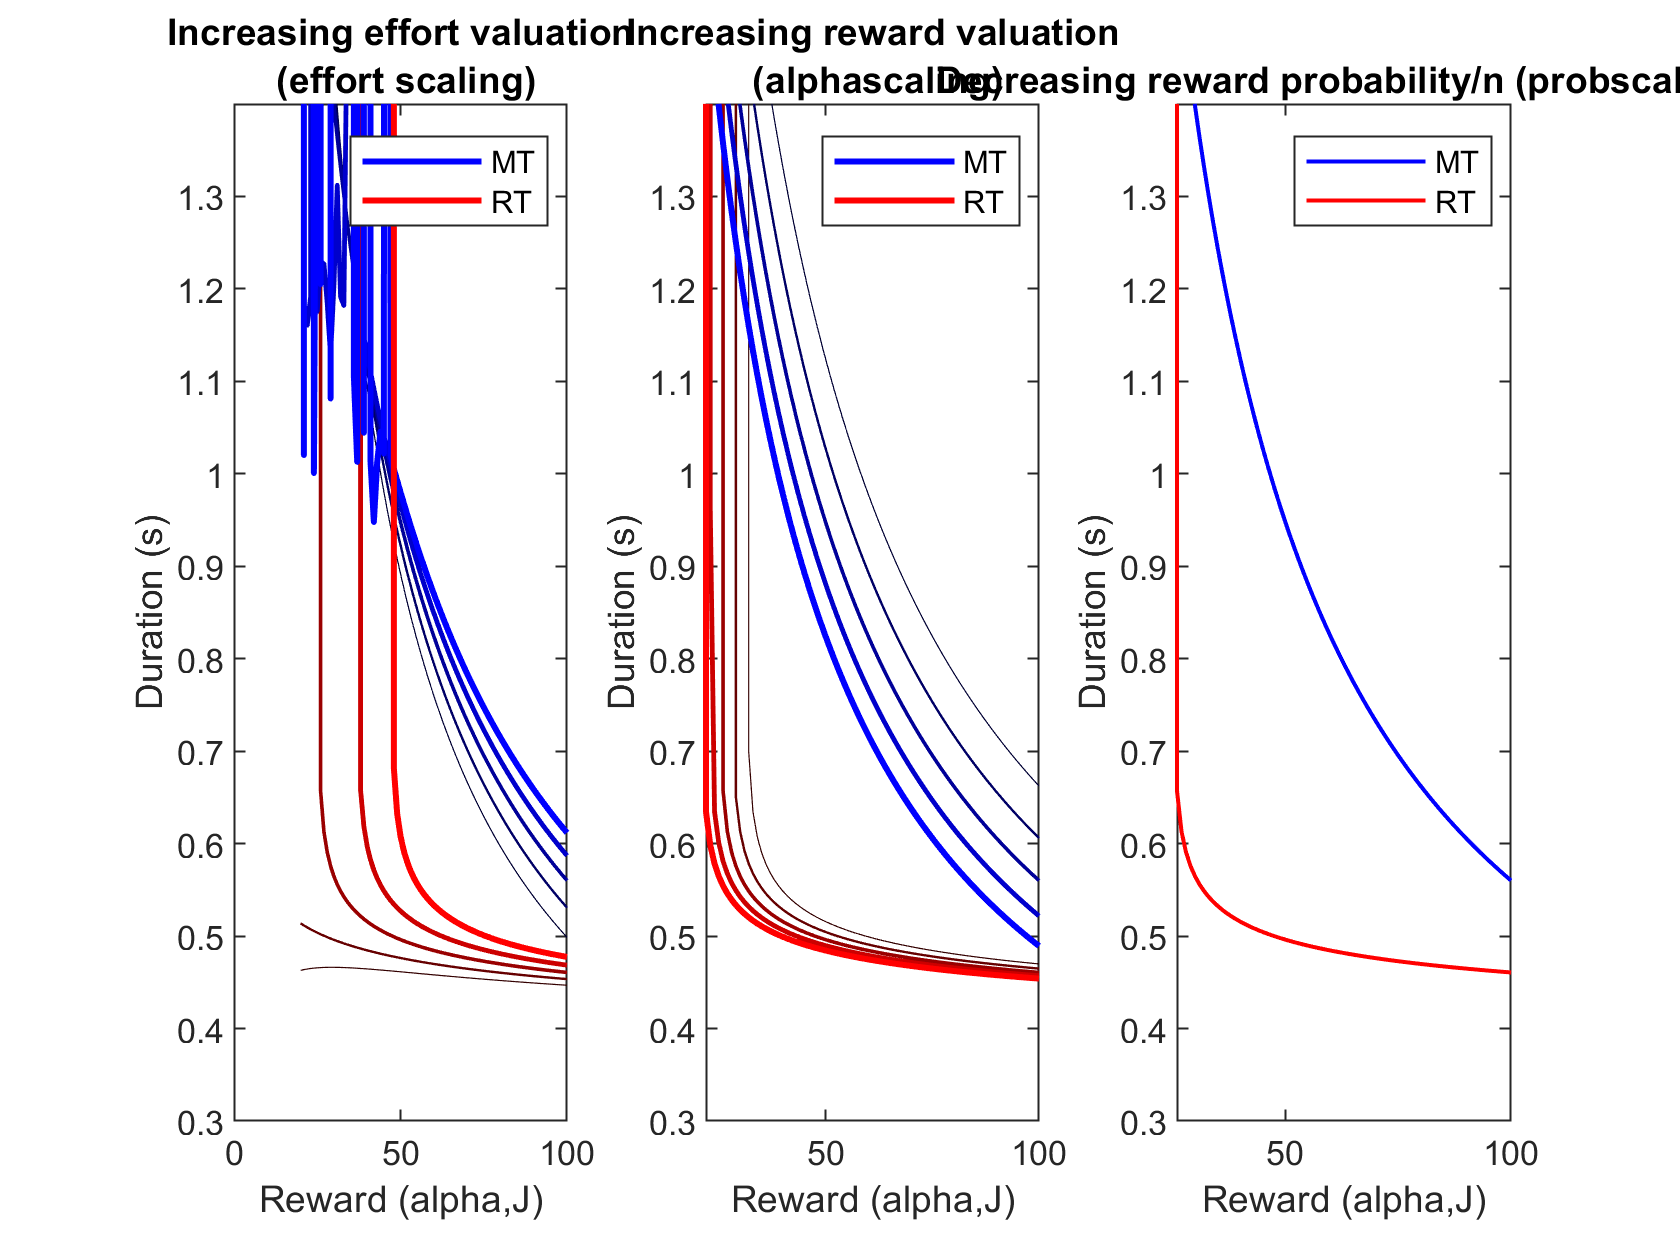

% Aggregate Figures
figure
%Effort Valuation Scaling
subplot(131)
for j=1:length(myeffscales)    
    h(:,j)=plot(myalphas,squeeze(mysols(:,j,alphascaleind,probscaleind,:)));
    hold on
    h(1,j).Color=j*[0 0 1]./length(myeffscales);
    h(2,j).Color=j*[1 0 0]./length(myeffscales);
    
    h(1,j).LineWidth=0.3*j;
    h(2,j).LineWidth=0.3*j;
end

title(sprintf(['Increasing effort valuation\n (effort scaling)']))
legend(h(:,j),'MT','RT')
xlabel('Reward (alpha,J)')
ylabel('Duration (s)')
set(gca,'ylim',[0.3 1.4])

%Reward Valuation Scaling
subplot(132)
for k=1:length(myalphascales)
    h(:,k)=plot(myalphas,squeeze(mysols(:,effscaleind,k,probscaleind,:)));
    hold on
    h(1,k).Color=k*[0 0 1]./length(myalphascales);
    h(2,k).Color=k*[1 0 0]./length(myalphascales);
    
    h(1,k).LineWidth=0.3*k;
    h(2,k).LineWidth=0.3*k;
end

title(sprintf(['Increasing reward valuation\n (alphascaling)']))
legend(h(:,k),'MT','RT')
xlabel('Reward (alpha,J)')
ylabel('Duration (s)')
set(gca,'ylim',[0.3 1.4])


%Probability Scaling
subplot(133)
for m=1:length(myprobscales)
    h(:,m)=plot(myalphas,squeeze(mysols(:,effscaleind,alphascaleind,m,:)));
    hold on
    h(1,m).Color=m*[0 0 1]./length(myprobscales);
    h(2,m).Color=m*[1 0 0]./length(myprobscales);
    
    h(1,m).LineWidth=0.2*m;
    h(2,m).LineWidth=0.2*m;
end


title(sprintf(['Decreasing reward probability/n (probscaling)']))
legend(h(:,m),'MT','RT')
xlabel('Reward (alpha,J)')
ylabel('Duration (s)')
set(gca,'ylim',[0.3 1.4])

**1) Movement TIme increases AND Reaction Time increases with**

a) increasing effort valuation (left plot, effort valuation increases with increasing line thickness and more blue/red color)

b) decreasing reward valuation (middle plot, reward valuation decreases with decreasing line thickness and more black color)

c) decreasing probability of reward (right plot, Pr(r) decreases with increasing line thickness and more blue/red color)

**2) Movement TIme increases AND Reaction Time decreases with increasing alpha (x-axis). This is true regardless of effort or reward valuation or prob of. reward.**

**Sensitivity of MT and RT to change in reward (at all alphas, grean are means across alphas)**

**a) With greater effort valuation**

- RT sensitivity increases

- MT sensitivity increases

- at some combinations of effort valuation and alpha, RT sensitivity will be greater than MT sensitivity

**b) With lower reward valuation**

- RT sensitivity increases

- MT sensitivity increases

- RT sensitivity is never greater than MT sensitivity

**c) With lower probability of reward**

- RT sensitivity decreases

- MT sensitivity decreases

- RT sensitivity is never greater than MT sensitivity